# ROC curve

**Author: CARLOS M N**

**DNI: XXXXXXXX-X**

Clear workspace

clear all; clc; close all;

## Initialize variables

Load table

churn = readtable('churn.csv');

**values**: actual churned cliets data

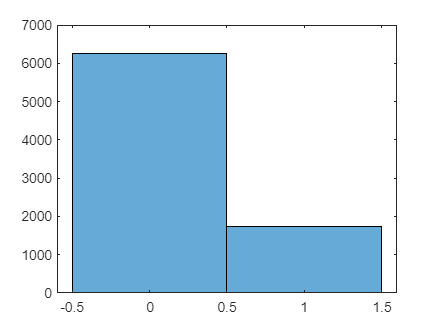

values = churn.Churned;
histogram(values)

**scores**: scores after model reconstruction with 2 most relevant variables

modelspec = ['Churned ~ Age + Churned_contacts'];
mdl = fitglm(churn, modelspec, Distribution='binomial');
scores = mdl.Fitted.Probability;

**threshold**: row vector of evenly spaced values

threshold = linspace(0,1,200);

## Compute matrix

prediction = scores>threshold;

## Get TP, TN, FP, FN matrixes

truepositive = prediction & values;
TP = sum(truepositive,1);

falsepositive = prediction & ~values;
FP = sum(falsepositive,1);

truenegative = ~prediction & ~values;
TN = sum(truenegative,1);

falsenegative = ~prediction & values;
FN = sum(falsenegative,1);

% Check
max(sum([TP; FP; TN; FN],1))

ans = 8000

min(sum([TP; FP; TN; FN],1))

ans = 8000

## Compute TPR and FPR and print

TPR = TP./(TP+FN);
FPR = FP./(FP+TN);

### plot

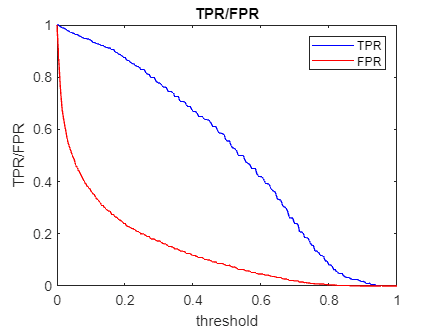

figure(2)
plot(threshold,TPR,'b')
hold on
plot(threshold,FPR,'r')
hold off
legend('TPR','FPR')
xlabel('threshold')
ylabel('TPR/FPR')
title('TPR/FPR')

## ROC curve

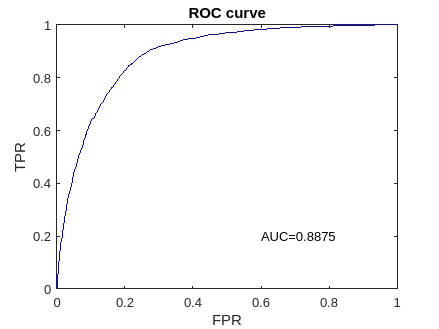

AUC = 0;
for ii=2:size(FPR,2)
    AUC = AUC + abs((FPR(ii)-FPR(ii-1)))*(TPR(ii)+TPR(ii-1))/2;
end

figure(3)
plot(FPR,TPR,'b')
xlabel('FPR')
ylabel('TPR')
text(0.6,0.2,strcat('AUC=',num2str(AUC)))
title('ROC curve')

saveas(gcf,'04_ROC/ROC_churn.png')